# Import AUTOSAR Package into Component Model

Import and reference shared ARXML element definitions.

## Add AUTOSAR Element Definitions to Model

When developing an AUTOSAR software component in Simulink, you can import AUTOSAR element definitions that are common to many components. After you create an AUTOSAR component model, you import the definitions from AUTOSAR XML (ARXML) files that contain packages of shared AUTOSAR elements. To help implement the component behavior, you want to reference predefined elements such as interfaces, data types, and software address methods (SwAddrMethods).

Suppose that you are developing an AUTOSAR software component model. You want to import predefined SwAddrMethod elements that are shared by multiple product lines and teams. This example uses AUTOSAR importer function [`updateAUTOSARProperties`](docid:autosar_ref.mw_533f6623-353e-405c-a6f1-fe23f99745f3) to import definitions from shared descriptions file `SwAddrMethods.arxml` into example model `autosar_swc`.

modelName = 'autosar_swc';
open_system(modelName);
ar = arxml.importer('SwAddrMethods.arxml');
updateAUTOSARProperties(ar,modelName);

The function copies the contents of the specified ARXML files to the AUTOSAR Dictionary of the specified model and generates an HTML report listing the element additions.

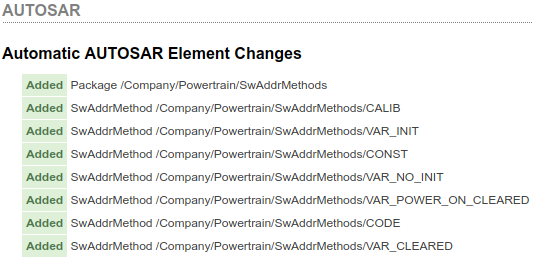

You can view the added elements as elements in the AUTOSAR Dictionary. By default, the elements are imported as read-only.

set_param(modelName,'SimulationCommand','update');  % Update diagram
autosar_ui_launch(modelName);  % Open AUTOSAR Dictionary

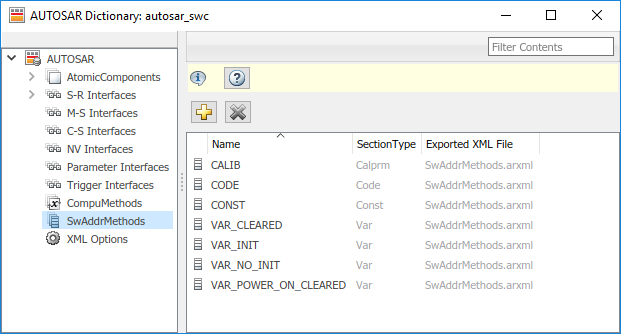

## Reference and Configure Imported AUTOSAR Elements

After importing the AUTOSAR elements to the software component model, you can reference and configure them in the same manner as any AUTOSAR Dictionary element. For example, use the AUTOSAR code perspective to apply imported SwAddrMethod definition CODE to a model entry-point function.

% Map step runnable function to SwAddrMethod CODE
slMap = autosar.api.getSimulinkMapping(modelName);
mapFunction(slMap,'Periodic:D1','Runnable_1s','SwAddrMethod','CODE');

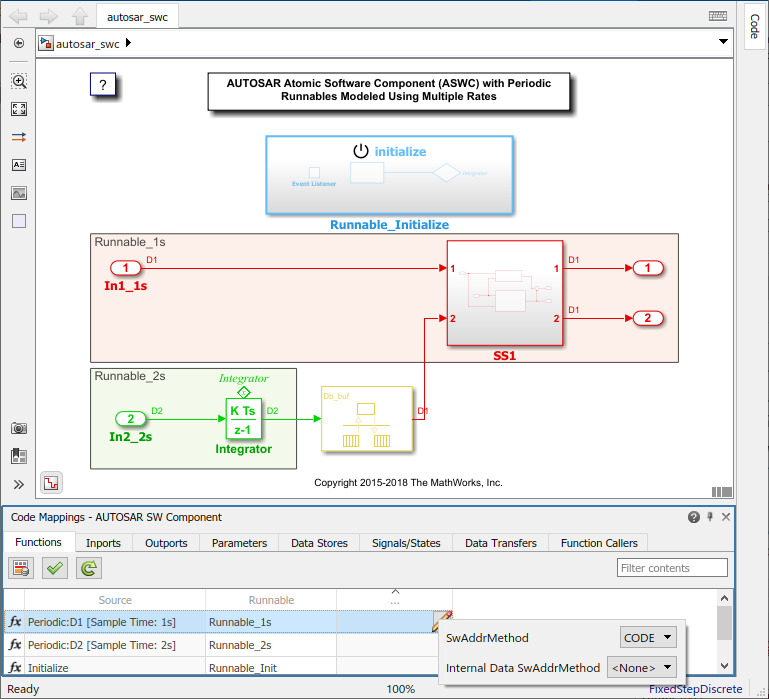

## Generate AUTOSAR C Code and XML Descriptions (Embedded Coder)

If you have Simulink Coder and Embedded Coder software, you can generate AUTOSAR-compliant C code and export ARXML descriptions from the model. To build the model, enter the command `slbuild(modelName);`.

Building the model generates an HTML code generation report. The C code contains a software address method CODE section.

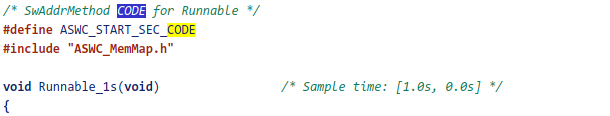

The ARXML descriptions define and reference SwAddrMethod CODE.

Export preserves the file structure and content of the shared descriptions file `SwAddrMethods.arxml` from which you added SwAddrMethod definitions.

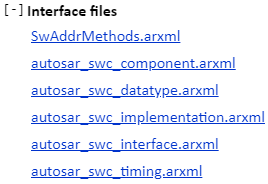

## Related Links

- [`updateAUTOSARProperties`](docid:autosar_ref.mw_533f6623-353e-405c-a6f1-fe23f99745f3)

- [Reuse AUTOSAR Element Descriptions](docid:autosar_ug.bvfyai7-1)

- [Import AUTOSAR XML Descriptions Into Simulink](docid:autosar_ug.briklfd-1)

*Copyright 2020 The MathWorks, Inc.*